addpath(".\functions\") % this line imports
% all functions inside the folder with
% the relative path "./functions/". 
% we use "." to select this current folder

s = tf("s") % define transfer function variable "s"

s =
 
  s
 
Continuous-time transfer function.
Model Properties



%numerator
numerator = 1

numerator = 1


%denominator
denominator = (s+2)*(s+3)

denominator =
 
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties



%transfer function
G = numerator / denominator

G =
 
        1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties



%get array of zeros
zeros_array = zero(G)


zeros_array =

  0×1 empty double column vector




%get array of poles
poles_array = pole(G)

poles_array =    -3.0000
   -2.0000



%get array of asymptote angles from array of poles and array of zeros
[asymptote_array, centroid] = asymptotes(zeros_array, poles_array, true)

asymptote_array =     90   270


centroid = -2.5000

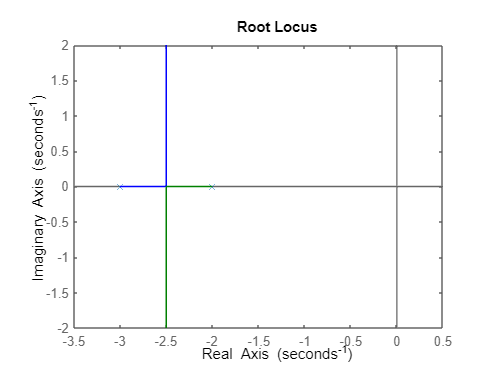



rlocus(G)